# Universal Meme Preferences

*Authors:* Max Brennan and Jonas Sangster

## Generative AI (genAI) Usage Statement

Write a short statement about how you used genAI on this assignment. *Note*: If you don't write anything, we'll assume you used genAI to write the whole thing!!!

*We used AI to reorganize the data from the way that it was originally in the CSV files into a way that makes sense, with a row for each round for each person, with a column for each meme the person had.*

*Generative AI was used to generate code to generate some graphs. The specifications of what the graphs should look like and what they should portray (i.e. x-axis, y-axis, type of graph, what data is fed into the graph) were determined by us.*

*Generative AI was also used to do code debugging for when matlab decided to *

## 1. Modeling Question

*(State your modeling question directly. Categorize it according to the action/specificity framework.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: we were curious about some question because of some reasons*

*B: but we weren't sure how to model it*

*T: so we did some background research for ideas (i.e. research synthesis matrix)*

*We were wondering if within the meme game, when choosing to spread and replace memes within your board, the memes that were chosen would be consistent for all players in the game. Because of this, we decided to have our modeling question be: Are preferences for one meme over another universal across all players in the 2022 meme game. We researched different ways that the spread of memes has been tracked over time, and focused specifically on how other people had used an agent based approach to modeling the spread of memes across a community, and found that a good way to validate our model would be through looking at one part of our data, then seeing if the patterns found in our data hold true by simulating the second half of the data, then comparing that simulated data to the second half of the data set to validate how well we were able to simulate the system by having the preferences for one meme to another remain constant. *

*Our model is relatively specific, as we are focused only on one year's worth of data, as we are specifically looking at the 2022 meme game, and are trying to discover if within the 2022 year the preferences for one meme over another remain constant. It is also relatively rhetorical, as there is not much that we will be able to do with the information we get, and it is more to discover some thing about that years meme game. The results are not applicable to other year's meme games, as we cannot extrapolate to other groups of people and other sets of memes.*

## 2. Literature Search

*(Identify 3 or more scholarly articles that are relevant to your modeling question. Analyze these references using the synthesis matrix approach. Report your synthesis matrix in a readable format: Include a link to a Google Sheet if it does not fit in the report.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*A: we learned X from article 1, Y from article 2, and Z from article 3*

*B: but we didn't find a direct answer to our modeling question*

*T: so we went on to build a model*

*Research Synthesis Matrix*

*When doing research we focused on finding how people had modeled the spread of memes across a population and ways to validate agent based models that would work for our usecases. Valenaise et al. (2021) provided insight on how we wanted to frame memes within our system, as well as provided insight on ways to show spread of memes, Weng et al. (2014) allowed us to learn more about how memes spread in a system, and gave us a possible way to validate our data, as they validated data through comparison to different regression models, and Datta et al. (2021) provided us with the validation model that we ended up going with, splitting the data into two subsections, training our system based on the first section, then using that trained data in comparison to the actual second half of the data to validate our model.*

## 3. Natural World

*Our model is representative of the processes of the meme game, in which each individual creates some drawing representative of a meme, then the individuals spread the memes around in the population. Each individual is only able to hold three memes however, meaning that over time there should be certain memes that are more popular than others. When modeling this system we wanted to make sure that we could accurately represent the different preferences for one meme over another that would be determined by the choices of the users in the system, as that is the information that will best allow for us to answer our question. Our determination of what the preferences are for one meme over another are based on three logial axioms: When a meme replaces another meme, the replaced meme is less desirable than the meme that replaces it; When a meme is replaced, the two memes that were not replaced are more desirable than the meme that was replaced; When a meme is chosen to be given to another person, it is more desirable than the other two memes.*

*Whilst these axioms can cover most cases in the meme game, there are some aspects that we are unable to track with this model. One common occurrence is that someone will be attached to the original meme that they create, giving it an inflated desirability for them in particular, as they will not want to get rid of that meme. Despite this aspect not being measured by our axioms, because we are measuring if there are universal preferences, not having a way for us to track these extra individual preferences that may be different from the overall desirability should have little effect on our final output. We also are assuming that there are no outside circumstances that would artificially inflate the desirability of a meme partway through the game, as any external influence would entirely invalidate the idea of a universal preference occurring over the course of the game.*

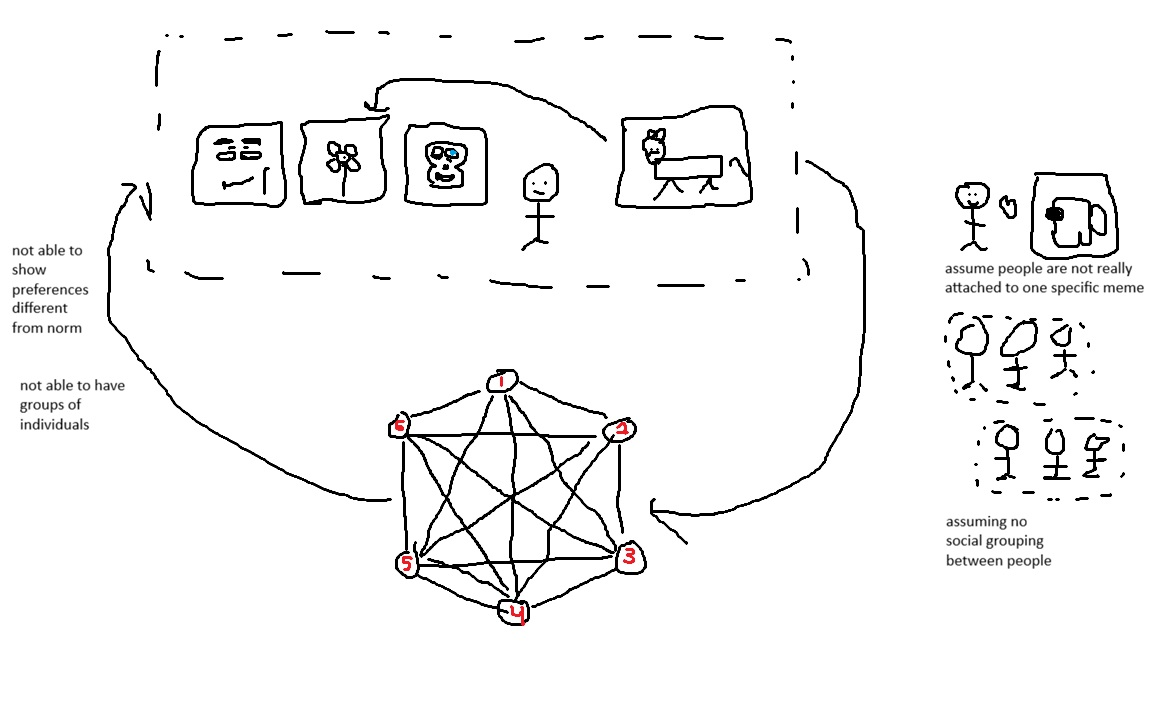

## 4. Model: Representation & Assumptions

*(Describe how your model represents the natural world. Use a tenchi diagram to illustrate what parts of the natural world are inside the system boundary. In the same tenchi diagram, provide a visual of your model. Describe in words how your model represents the chosen system. Describe in words what assumptions you have made. Cite your references when appropriate.)*

*(You will likely need to write 5-7 code & text regions for this section. You should have images and equations to describe your model, and then implement your model in code.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: this part of the natural world is important for our question*

*B: but we can't include that directly because of X reason*

*T: so here is the way we represented it / what we assumed to simplify*

In our model, we only represent the meme trading aspects of the natural world, being that of passing on a meme to another person, then taking that meme that you were given and replacing a meme within your board. We first began by taking the data and set it up in a way that we can use for training, by splitting it into two sections so that we can use the first half to train the data. By doing this instead of a parameter sweep we have a much better, more accurate way to validate our data, as our goal is to determine whether preferences for memes will remain over the time period, and by training off of the inital half of the data, we can see whether preferences stay by comparing to the second half of the data.

data2022 = readtable("Meme_Game_Results_export\2022\meme-processed.csv"); 

%Set up meme tracking in system
allMemes2022 = [data2022.slot1; data2022.slot2; data2022.slot3];
uniqueMemes2022 = unique(allMemes2022(~isnan(allMemes2022))); %every meme that shows up in any slot
memeTracking = [];
%memePreferences(r,c) = number of times meme c beat meme r (rows and columns both use uniqueMemes2022)
memePreferences = zeros(length(uniqueMemes2022),length(uniqueMemes2022));
trainingRounds = round(max(data2022.round) / 2); % arbitrary value, set to how long you want to train data (later rounds are used for validation in section 5)

Once we had the data in sections we had to be able to use the first half to figure out which memes were preferred over other memes. We began by creating a loop to go through every unique meme in the system, and find all interactions involving that meme

%Starting at round 3, loop through all memes
for i = 1 : length(uniqueMemes2022)
    currentMeme = uniqueMemes2022(i);
    currentInteraction = 1;
    %loop through and find all interactions of that meme

We then looped through all individual interactions within the meme game, and found the interactions involving a specific meme. We also had to account for the first two rounds where there is no replacement, and only adding to the meme deck for each person, so we skipped those rounds as they will not give us information on what meme is better than another meme.

    for j = 1 : length(data2022.round)
        if data2022.round(j) > 2 && data2022.round(j) <= trainingRounds
            personCurrentMemes = [data2022.slot1(j);data2022.slot2(j);data2022.slot3(j)];
            if ismember(currentMeme, personCurrentMemes)
                %find this person's hand in the previous round
                lastIndex = find(data2022.student == data2022.student(j) & data2022.round == data2022.round(j) - 1, 1);
                if isempty(lastIndex)
                    continue; %previous round is missing
                end
                personOldMemes = [data2022.slot1(lastIndex);data2022.slot2(lastIndex);data2022.slot3(lastIndex)];
                if any(isnan([personOldMemes; personCurrentMemes]))
                    continue; %hand has an empty slot
                end

We then do some management to help prevent any issues with the data, and find which meme was replaced, and which meme was received in the system.

                %compare as sets so reordered hands still work
                replacedMeme = setdiff(personOldMemes, personCurrentMemes);
                receivedMeme = setdiff(personCurrentMemes, personOldMemes);
                if length(replacedMeme) ~= 1 || length(receivedMeme) ~= 1
                    continue; %no swap this round, or more than one meme changed (bad data)
                end
                replacedIndex = find(uniqueMemes2022 == replacedMeme, 1);

After this point we are finally able to do the analysis on whether 

                if ismember(currentMeme,personOldMemes) ~= 1
                    %currentMeme was received, so it beat the meme it replaced
                    memePreferences(replacedIndex,i) = memePreferences(replacedIndex,i) + 1;

                    %currentMeme was also picked over the partner's other memes
                    lastIndexPartner = find(data2022.student == data2022.partner(j) & data2022.round == data2022.round(j) - 1, 1);
                    if ~isempty(lastIndexPartner)
                        partnerOldMemes = [data2022.slot1(lastIndexPartner);data2022.slot2(lastIndexPartner);data2022.slot3(lastIndexPartner)];
                        if ismember(currentMeme, partnerOldMemes)
                            partnerOtherMemes = unique(partnerOldMemes(partnerOldMemes ~= currentMeme & ~isnan(partnerOldMemes)));
                            for m = 1:length(partnerOtherMemes)
                                memeIndex = find(uniqueMemes2022 == partnerOtherMemes(m), 1);
                                memePreferences(memeIndex,i) = memePreferences(memeIndex,i) + 1;
                            end
                        end
                    end

                elseif ismember(currentMeme,personOldMemes) == 1
                    %currentMeme was kept, so it beat the meme that was replaced
                    memePreferences(replacedIndex,i) = memePreferences(replacedIndex,i) + 1;

                else
                    fprintf("if you are reading this, then formal logic is broken. you are fucked. go to bed.");
                end

                memeTracking(currentInteraction,1,i) = personOldMemes(1,1);
                memeTracking(currentInteraction,2,i) = personOldMemes(2,1);
                memeTracking(currentInteraction,3,i) = personOldMemes(3,1);
                memeTracking(currentInteraction,4,i) = personCurrentMemes(1,1);
                memeTracking(currentInteraction,5,i) = personCurrentMemes(2,1);
                memeTracking(currentInteraction,6,i) = personCurrentMemes(3,1);
                currentInteraction = currentInteraction + 1;
            end
        end
    end
end

%Head-to-head win percentage for every pair of memes that met
%winPercent(r,c) = fraction of the matchups between memes r and c that meme c won
totalMatchups = memePreferences + memePreferences';
winPercent = memePreferences ./ totalMatchups; %NaN for pairs that never met

%List every head-to-head result that has a winner
[loserList, winnerList] = find(winPercent > 0.5);
strength = winPercent(sub2ind(size(winPercent), loserList, winnerList));
matchups = totalMatchups(sub2ind(size(totalMatchups), loserList, winnerList));

%Sort from strongest to weakest (if two are equally strong, the one with more matchups goes first)
[~, order] = sortrows([strength matchups], [-1 -2]);

%Add results strongest first. If a result would close a loop, it is the weakest
%connection in that loop (everything already added is stronger), so skip it.
A = zeros(size(memePreferences)); %A(r,c) = 1 if meme c is better than meme r
brokenConnections = 0;
for k = 1:length(order)
    winner = winnerList(order(k));
    loser = loserList(order(k));
    if A(winner, loser) == 1
        brokenConnections = brokenConnections + 1; %loser already beats winner through a chain, so this closes a loop
        continue;
    end
    %winner (and every meme better than it) now beats loser (and every meme worse than it)
    betterMemes = [winner, find(A(winner,:))];
    worseMemes = [loser; find(A(:,loser))];
    A(worseMemes, betterMemes) = 1;
end
meme_ids = uniqueMemes2022'; %meme ID for each row/column of A, used in section 5


## 5. Verification & Validation

At this point, we have a matrix A that represents a hierarchy in preferences for memes. For instance, let's look at the following diagram

% Generative AI was used to generate the next 12 lines of code.
%% Diagram 1: 2 nodes, arrow from node 1 to node 2
G1 = digraph(1, 2);

figure('Name', 'Figure 1');
plot(G1, ...
    'XData', [0 1], 'YData', [0 0], ...
    'MarkerSize', 12, 'NodeFontSize', 14, ...
    'LineWidth', 2, 'ArrowSize', 15, ...
    'NodeColor', [0.2 0.4 0.8], 'EdgeColor', 'k');
title('Figure 1');
axis off; axis equal;
xlim([-0.3 1.3]); ylim([-0.5 0.5]);

In figure 1, we have 2 memes: meme 1 and meme 2. As represented by the arrow, meme 1 is better than meme 2. We can represent this with the following matrix:


$$\left\lbrack \begin{array}{cc}
0 & 0\\
1 & 0
\end{array}\right\rbrack$$
 

In this matrix, we let each row represent a meme, and each column represent a meme. Whenever a value is equal to one, it means the meme of the corresponding column is more preferable than the meme of the corresponding row. In this example, the value at row 2, column 1 is equal to 1, meaning meme 1 is better than meme 2. Let's look at another example.

% Generative AI was used to generate the next 12 lines of code.
%% Diagram 2: 2 nodes, bidirectional arrow between 1 and 2
G2 = digraph([1 2], [2 1]);   % 1->2 and 2->1

figure('Name', 'Figure 2');
plot(G2, ...
    'XData', [0 1], 'YData', [0 0], ...
    'MarkerSize', 12, 'NodeFontSize', 14, ...
    'LineWidth', 2, 'ArrowSize', 15, ...
    'NodeColor', [0.2 0.4 0.8], 'EdgeColor', 'k');
title('Figure 2');
axis off; axis equal;
xlim([-0.3 1.3]); ylim([-0.5 0.5]);

In the case of figure 2, the arrow is bidirectional. This means that meme 2 and meme 1 are equally as preferable, as represented by the following matrix:


$$\left\lbrack \begin{array}{cc}
0 & 1\\
1 & 0
\end{array}\right\rbrack$$


Let's look at one final example of how we can incorporate both of these concepts

% Generative AI was used to generate the next 23 lines of code.
%% Diagram 3: 4 nodes
%   4 -> 3
%   2 <-> 3
%   3 -> 1
s = [4 2 3 3];
t = [3 3 2 1];
G3 = digraph(s, t);

% Layout: node 3 in the center, others around it
%        1
%   4    3    2
x = [0  1  0 -1];   % x-positions for nodes 1..4
y = [1  0  0  0];   % y-positions for nodes 1..4

figure('Name', 'Figure 3');
plot(G3, ...
    'XData', x, 'YData', y, ...
    'MarkerSize', 12, 'NodeFontSize', 14, ...
    'LineWidth', 2, 'ArrowSize', 15, ...
    'NodeColor', [0.2 0.4 0.8], 'EdgeColor', 'k');
title('Figure 3');
axis off; axis equal;
xlim([-1.4 1.4]); ylim([-0.5 1.4]);

Figure 3 can be translated into matrix form like so:


$$\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 1 & 0\\
0 & 1 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


This matrix effectively conveys all 4 nodes and their relationships with neighboring nodes, but it does NOT tell us about any implied relationships. Let's see what these implied relationships would look like.

% Generative AI was used to generate the next 30 lines of code.
%% Diagram 4: Diagram 3 plus dotted arrows 4->1, 4->2, 2->1
%   Solid:  4 -> 3,  2 <-> 3,  3 -> 1
%   Dotted: 4 -> 1,  4 -> 2,   2 -> 1
sSolid  = [4 2 3 3];
tSolid  = [3 3 2 1];
sDotted = [4 4 2];
tDotted = [1 2 1];

G4 = digraph([sSolid sDotted], [tSolid tDotted]);

% Layout: node 3 in the center of a triangle formed by 1, 2, 4
%          1
%          3
%     4         2
x = [0   1    0  -1];     % x-positions for nodes 1..4
y = [1  -0.6  0  -0.6];   % y-positions for nodes 1..4

figure('Name', 'Figure 4');
p = plot(G4, ...
    'XData', x, 'YData', y, ...
    'MarkerSize', 12, 'NodeFontSize', 14, ...
    'LineWidth', 2, 'ArrowSize', 15, ...
    'NodeColor', [0.2 0.4 0.8], 'EdgeColor', 'k');

% Make only the new edges dotted
highlight(p, sDotted, tDotted, 'LineStyle', ':');

title('Figure 4');
axis off; axis equal;
xlim([-1.4 1.4]); ylim([-1 1.4]);

In figure 4, we can see that since meme 4 is preferable to meme 3, and meme 3 is preferable to meme 1, then meme 4 is preferable to meme 1. This is how it would look in matrix form


$$\left\lbrack \begin{array}{cccc}
0 & 1 & 1 & 1\\
0 & 0 & 1 & 1\\
0 & 1 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Now that we understand what information this matrix conveys, let's verify it fits our criteria.

% Check the preference matrix A built in section 4

% All diagonal elements are zero
assert(all(~diag(A)), 'Diagonal is not zero');

% All elements are zero or one
assert(all(A(:) == 0 | A(:) == 1))

% If one there is a symmetric one, all values (except in the diagonal)
% must be equal in those columns 
sym_ones = A & A';
for row = 1:size(A, 1)
    for col=1:size(A, 2)
        if (~sym_ones(row,col))
            continue;
        end
        % At this point, A(row,col) is a symmetric 1
        % Check that 2 columns are equal
        adjusted_A = A + eye(size(A,1));
        assert(all(adjusted_A(:,row) == adjusted_A(:,col)), 'Memes with equal preference do not have similar columns');
    end
end

% If meme A is better than meme B, then meme A must be better
% than all memes that B is better than.
asym_ones = xor(A, A') & A;
for row = 1:size(A, 1)
    for col=1:size(A, 2)
        if (~asym_ones(row,col))
            continue;
        end
        
        % Right now, meme A = {COL}; meme B = {ROW}.
        % For each item in column number {ROW}, if that item is one, then
        % The corresponding item in column number {COL} must also be one
        assert(all(~A(:,row) | A(:,col)), 'Memes do not inherit preferences from lower memes');
    end
end

disp('Assertions passed!')

Before moving on, we need to define some vocabulary to better understand our validation process. The matrix above is known as **matrix A.** For each timestep, all pairs of players in the meme game perform a **transaction**. In each transaction, both players replace one of their memes with a new meme, the **received meme**. The two unreplaced memes are **ignored memes**. For each ignored meme, we compare to the received meme. If the ignored meme is better than the received meme (according to matrix A), then we made a **correct prediction**. If the ignored meme is worse than the received meme, we made an **incorrect prediction**.

To validate our data, we measure what proportion of our predictions are correct predictions. If a supermajority (80%) of our predictions are correct, then we assume that there is a universal preference for one meme over another.

%% Data from model and CSV
% Validate on the rounds that were not used to build A in section 4.
% Round trainingRounds is kept so the first validation round has a hand to compare against.
all_data = table2array(data2022); % Columns: student, round, partner, slot1, slot2, slot3
validation_data = all_data(all_data(:,2) >= trainingRounds, :);

first_round = min(validation_data(:,2));
val_data_with_first_round = validation_data;
validation_data = validation_data(validation_data(:,2) ~= first_round, :); % Removes first round from data

correct_predictions = zeros(1,size(validation_data,1));
incorrect_predictions = zeros(1,size(validation_data,1));

% Loop through each row of validation_data
for i=1:size(validation_data,1)
    transaction = validation_data(i,:);
    same_player_rows = val_data_with_first_round(:,1) == transaction(1);
    prev_round_rows = val_data_with_first_round(:,2) == transaction(2)-1;

    % See which memes have changed
    memes_before_transaction = val_data_with_first_round(same_player_rows & prev_round_rows, 4:6);
    % Skip if the previous round is missing or the hand was not full yet
    if isempty(memes_before_transaction) || any(isnan(memes_before_transaction(1,:)))
        continue;
    end
    memes_before_transaction = memes_before_transaction(1,:);
    memes_after_transaction = transaction(4:6);
    memes_changed = memes_before_transaction ~= memes_after_transaction;
    if (any(memes_changed))
        meme_replaced = memes_before_transaction(memes_changed);
        meme_received = memes_after_transaction(memes_changed);
        meme_replaced = meme_replaced(1);
        meme_received = meme_received(1);
    else
        % Hand did not change, so the received meme is one the partner had that this player already held
        partner_rows = val_data_with_first_round(:,1) == transaction(3) & val_data_with_first_round(:,2) == transaction(2)-1;
        partner_memes = val_data_with_first_round(find(partner_rows, 1), 4:6);
        % Generative AI was used to generate the next 4 lines of code.
        meme_received = intersect(partner_memes, memes_after_transaction);
        if numel(meme_received) ~= 1
            continue;
        end
        meme_replaced = meme_received; % The received meme replaced itself
    end

    % Setup to count correct and incorrect predictions
    memes_ignored = unique(memes_before_transaction(memes_before_transaction ~= meme_replaced));
    memes_predicted_correctly = zeros(size(memes_ignored));
    memes_predicted_incorrectly = zeros(size(memes_ignored));

    % Loop through all ignored memes
    meme_received_idx = find(meme_ids == meme_received, 1);
    for j=1:numel(memes_ignored)
        meme_ignored = memes_ignored(j);
        meme_ignored_idx = find(meme_ids == meme_ignored, 1);
        % If meme_received is better than meme_ignored, we predicted incorrectly
        if (A(meme_ignored_idx, meme_received_idx))
            if (~A(meme_received_idx, meme_ignored_idx))
                memes_predicted_incorrectly(j) = 1;
            end
        % If meme_received is worse than meme_ignored, we predicted correctly.
        elseif (A(meme_received_idx, meme_ignored_idx))
            memes_predicted_correctly(j) = 1;
        end
    end

    % Sum up final prediction counts
    correct_predictions(i) = sum(memes_predicted_correctly);
    incorrect_predictions(i) = sum(memes_predicted_incorrectly);
end

## 6. Claims & Limitations

% Print out final validation value
percent_predictions_correct = sum(correct_predictions) / (sum(correct_predictions) + sum(incorrect_predictions))

About 67% of our predictions are correct. Since 48.67% < 80%, we conclude that there is no universal preference for one meme over another. Let's take a look at some characteristics of our predictions when put in context with other data to ensure that there are no extreme outliers causing this drop to around 50%.

%% Percent of predictions correct by round
rounds = unique(validation_data(:,2));
percent_correct_by_round = NaN(size(rounds));

% Loop through each round
for i=1:numel(rounds)
    round_rows = validation_data(:,2) == rounds(i);
    correct_in_round = sum(correct_predictions(round_rows));
    total_in_round = correct_in_round + sum(incorrect_predictions(round_rows));
    if (total_in_round == 0)
        continue;
    end
    percent_correct_by_round(i) = 100 * correct_in_round / total_in_round;
end

figure('Name', 'Percent Correct by Round');
plot(rounds, percent_correct_by_round, '-o', 'LineWidth', 2);
yline(80, '--', '80% threshold');
xlabel('Round');
ylabel('Predictions correct (%)');
title('Figure 5');
ylim([0 100]);

As shown by the graph above, the trend of predictions correct remains fairly stable throughout time, so we cannot attribute a lack of universal preference to boredom, or changing of preferences over time. Let's see if there are any memes that are significantly more polarizing or universal than others.

%% Percent of predictions correct by meme
min_predictions = 5; % Memes/players with fewer predictions than this are left out
bin_width = 5; % Width of each dot plot column, in percent

% A transaction's predictions count toward every meme in the hand after it
% (the received meme and the ignored memes)
memes = unique(validation_data(:, 4:6));
memes = memes(~isnan(memes));
percent_correct_by_meme = NaN(size(memes));

% Loop through each meme
for i=1:numel(memes)
    meme_rows = any(validation_data(:, 4:6) == memes(i), 2);
    correct_with_meme = sum(correct_predictions(meme_rows));
    total_with_meme = correct_with_meme + sum(incorrect_predictions(meme_rows));
    if (total_with_meme < min_predictions)
        continue;
    end
    percent_correct_by_meme(i) = 100 * correct_with_meme / total_with_meme;
end

% Stack one dot per meme in bins of bin_width percent
meme_bins = round(percent_correct_by_meme(~isnan(percent_correct_by_meme)) / bin_width) * bin_width;
meme_dot_heights = zeros(size(meme_bins));
for i=1:numel(meme_bins)
    meme_dot_heights(i) = sum(meme_bins(1:i) == meme_bins(i));
end

figure('Name', 'Percent Correct by Meme');
scatter(meme_bins, meme_dot_heights, 60, 'filled');
xline(80, '--', '80% threshold');
xlabel('Predictions correct (%)');
ylabel('Number of memes');
title('Percent of Predictions Correct by Meme');
xlim([-bin_width 100+bin_width]);
ylim([0 max(meme_dot_heights)+1]);

The distribution of memes is approximately normal for different measures of correct predictions, and they are all clustered around the 50% mark. This eliminates the possibility that a particularly controversial meme could be skewing the data.

%% Percent of predictions correct by player
players = unique(validation_data(:,1));
percent_correct_by_player = NaN(size(players));

% Loop through each player
for i=1:numel(players)
    player_rows = validation_data(:,1) == players(i);
    correct_by_player = sum(correct_predictions(player_rows));
    total_by_player = correct_by_player + sum(incorrect_predictions(player_rows));
    if (total_by_player < min_predictions)
        continue;
    end
    percent_correct_by_player(i) = 100 * correct_by_player / total_by_player;
end

% Stack one dot per player in bins of bin_width percent
player_bins = round(percent_correct_by_player(~isnan(percent_correct_by_player)) / bin_width) * bin_width;
player_dot_heights = zeros(size(player_bins));
for i=1:numel(player_bins)
    player_dot_heights(i) = sum(player_bins(1:i) == player_bins(i));
end

figure('Name', 'Percent Correct by Player');
scatter(player_bins, player_dot_heights, 60, 'filled');
xline(80, '--', '80% threshold');
xlabel('Predictions correct (%)');
ylabel('Number of players');
title('Figure 7');
xlim([-bin_width 100+bin_width]);
ylim([0 max(player_dot_heights)+1]);

In addition to there being no controversial memes, there are no players that are significantly more or less predictable than other players of the meme game. All players seem to cluster around the 50% mark in an approximately normal distribution.

While figure 5 provides sufficient evidence to rule out our assumption that people don't get bored of a meme as a possible limitation to our results, there are still some factors that could be introducing limitations into our results. For instance, players may be more likely to favor the first meme they drew, which could negatively impact the prediction scores for every meme. Additionally, we assumed that any given individual is equally as likely to pass a meme on to a stranger than to a friend they know. This could make prediction accuracy appear higher than reality since social circles may be more likely to share similar meme preferences, but meme preferences between social circles may be vastly different.

Our model parameters were also narrowly scoped to the first half of the year of 2022, and validated against the second half of 2022. Since 2022 only had about 30 rounds, this means that the model and validation only worked with 15 rounds each, which is potentially insignificant to evaluate complex social implications.

## 7. Conclusion

Are preferences for one meme over another universal across all players in the 2022 meme game?

We conclude that preferences for one meme over another are NOT universal across all players in the 2022 meme game. When validating the universal preferences in the second half of the data, we reached an accuracy very close to 50%, which can be attributed to random chance. Additionally, the prediction accuracy remained very stable over time, and the distributions of people and memes compared to prediction accuracy were approximately normal, which made it highly unlikely that our results could have been skewed by bad data.

## 8. Future Work

In this paper, we came to the conclusion that there are not universal preferences for one meme over another. In the future, we could take an approach focused on each individual. That is, do meme preferences for an individual change over time? Earlier, we assumed that they didn't. However, it is certainly possible that an individual may get "bored" of a meme after holding it for many rounds. We could explore this behavior, and if we find sufficient evidence that it's true, then we could re-examine this paper to see if this behavior has any effect on the lack of universal preference we saw.

Additionally, we could compare and contrast results from multiple years of the meme game. One could argue that the small sample size associated with our data makes it infeasible to draw accurate conclusions on universal preferences. Different years also have different groups of people which could lead to different, unforeseen results.

## References

*(List all references alphabetically by last name. Use the following format: Last name 1, Last name 2, ... (Year) "Title of Reference")*